**EDO Orden Superior -> Sistemas EDO de Primer Orden**

clear;

% Párametros del problema:
t0 = 0, tf = 5

t0 = 0

tf = 5

% Condiciones iniciales:
x10 = 1, x20 = 0

x10 = 1

x20 = 0

**Solución Exacta**

syms y(t)
Dy = diff(y,t);
D2y = diff(y,t,2);
sol = dsolve(D2y == -(3/4)*Dy - (1/4)*cos(t),y(0)==1,Dy(0)==0);
sol = matlabFunction(sol);
tt = t0:0.1:tf; tt = tt';
y_exac = sol(tt);

**SEDO - PVI:**

% Funciones del S.EDO:
F = @(t,z) [ z(2)
            -(3/4)*z(2) - (1/4)*cos(t) ];
% C.I:
y0 = [x10 x20]';
% Paso h:
h = 1;

**Solución Numérica con Euler:**

[iter,t_euler,z_euler,FF] = eulerV(F,t0,tf,y0,h);

T = table(iter,t_euler,z_euler,FF,'VariableNames',{'iter','t_euler','z_euler','FF'});
disp(T)

    iter    t_euler          z_euler                   FF          
    ____    _______    ___________________    _____________________

     0         0             1           0           0        -0.25
     1         1             1       -0.25       -0.25     0.052424
     2         2          0.75    -0.19758    -0.19758      0.25222
     3         3       0.55242    0.054643    0.054643      0.20652
     4         4       0.60707     0.26116     0.26116    -0.032458
     5         5       0.86823      0.2287           0            0



**Solución Numérica con RK2:**

[iter,t_RK2,z_RK2,K1,K2] = RK2V(F,t0,tf,y0,h);

T = table(iter,t_RK2,z_RK2,K1,K2,'VariableNames',{'iter','t_RK2','z_RK2','K1','K2'});
disp(T)

    iter    t_RK2           z_RK2                      K1                       K2          
    ____    _____    ____________________    ______________________    _____________________

     0        0            1            0            0        -0.25       -0.25     0.052424
     1        1        0.875    -0.098788    -0.098788    -0.060985    -0.15977      0.22387
     2        2      0.74572    -0.017347    -0.017347      0.11705      0.0997      0.17272
     3        3       0.7869      0.12754      0.12754      0.15184     0.27938    -0.046126
     4        4      0.99036       0.1804       0.1804     0.028113     0.20851      -0.2273
     5        5       1.1848     0.080805            0            0           0            0



**Gráfica Comparativa:**

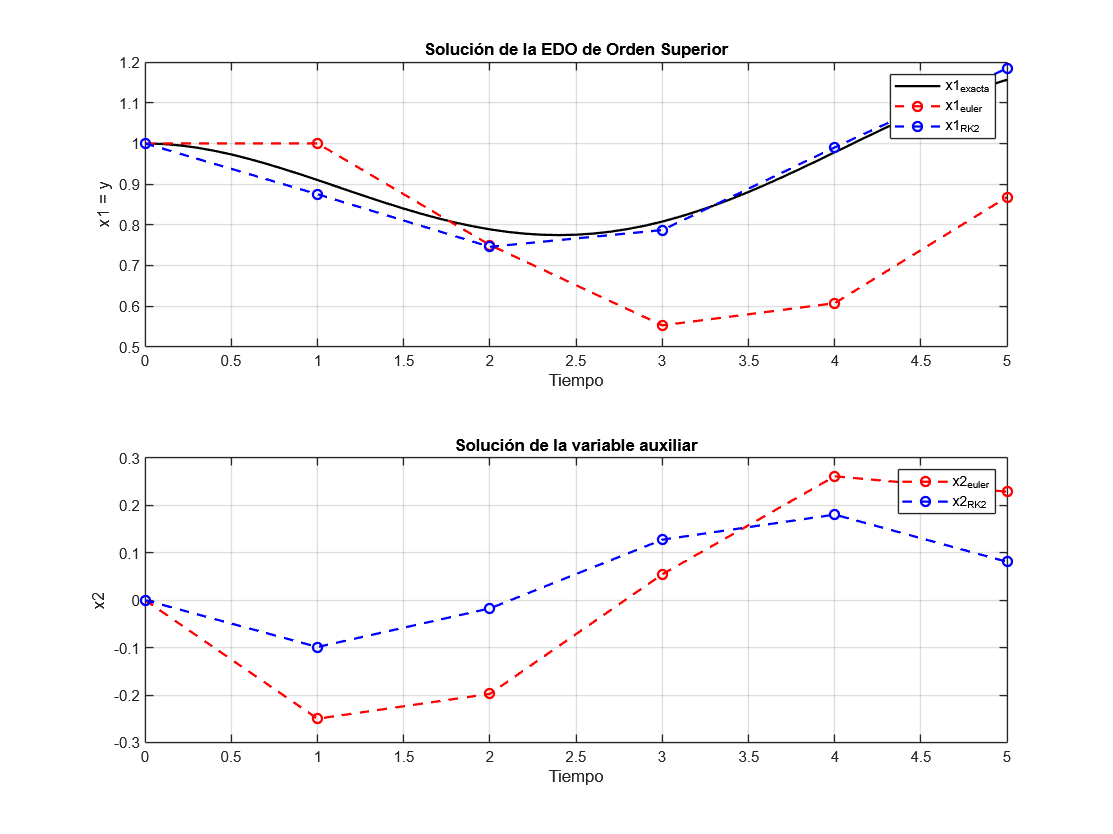

figure(1); clf;

subplot(2,1,1);
plot(tt,y_exac,'-k','LineWidth',1.5); grid on; hold on;
plot(t_euler,z_euler(:,1),'--or','LineWidth',1.5);
plot(t_RK2,z_RK2(:,1),'--ob','LineWidth',1.5);
xlabel('Tiempo');
ylabel('x1 = y');
legend('x1_{exacta}','x1_{euler}','x1_{RK2}');
title('Solución de la EDO de Orden Superior');

subplot(2,1,2);
plot(t_euler,z_euler(:,2),'--or','LineWidth',1.5); grid on; hold on;
plot(t_RK2,z_RK2(:,2),'--ob','LineWidth',1.5);
xlabel('Tiempo');
ylabel('x2');
title('Solución de la variable auxiliar');
legend('x2_{euler}','x2_{RK2}');

function [iter,t_euler,y_euler,FF] = eulerV(F,t0,tf,y0,h)
    t_euler = t0:h:tf; t_euler = t_euler';
    iter = 0:length(t_euler)-1; iter = iter';
    m = length(t_euler);
    n = length(y0);
    y_euler = zeros(m,n);
    FF = zeros(m,n);
    y_euler(1,:) = y0;
    for i = 1:length(t_euler)-1
        FF(i,:) = F(t_euler(i,1),y_euler(i,:));
        y_euler(i+1,:) = y_euler(i,:) + h*FF(i,:);
    end
end

function [iter,t_RK2,y_RK2,K1,K2] = RK2V(F,t0,tf,y0,h)
    t_RK2 = t0:h:tf; t_RK2 = t_RK2';
    iter = 0:length(t_RK2)-1; iter = iter';
    m = length(t_RK2);
    n = length(y0);
    y_RK2 = zeros(m,n);
    K1 = zeros(m,n);
    K2 = zeros(m,n);
    y_RK2(1,:) = y0;
    for i = 1:length(t_RK2)-1
        K1(i,:) = F(t_RK2(i,1),y_RK2(i,:));
        K2(i,:) = F(t_RK2(i,1)+h,y_RK2(i,:)+h*K1(i,:));
        y_RK2(i+1,:) = y_RK2(i,:) + h*(0.5*K1(i,:)+0.5*K2(i,:));
    end
end